## Lab 1 - Simulation

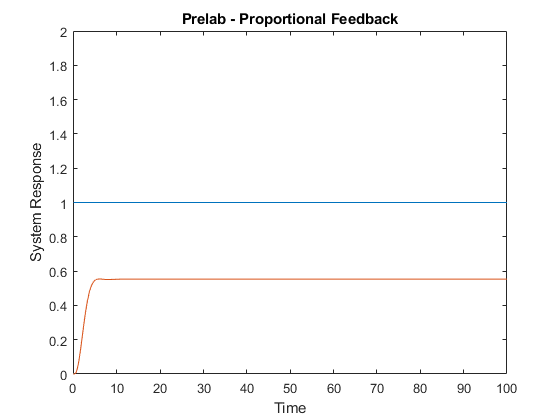

load("dataset021.mat");
open_system('Lab1_Prelab.slx');
sim('Lab1_Prelab.slx');
load("PreL1_Out.mat");
close_system('Lab1_Prelab.slx');

plot(PreL1_Out.signal1);
hold on;
plot(PreL1_Out.signal2);
hold off;
axis([-0.1 100 0 2]);
xlabel("Time");
ylabel("System Response");
title("Prelab - Proportional Feedback");

### Part 1 - P

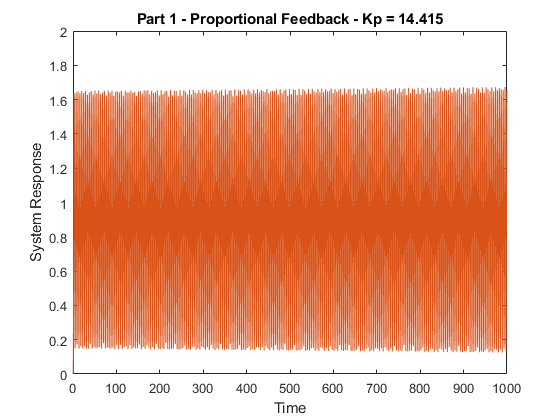

open_system('Lab1_P.slx');
set_param('Lab1_P/Kp', 'Gain', num2str(14.415));
sim('Lab1_P.slx');
load("L1_P_Out.mat");
close_system('Lab1_P.slx');

plot(L1_P_Out.signal1);
hold on;
plot(L1_P_Out.signal2);
hold off;
axis([-0.1 1000 0 2]);
xlabel("Time");
ylabel("System Response");
title("Part 1 - Proportional Feedback - Kp = 14.415");

### Part 2 - PI

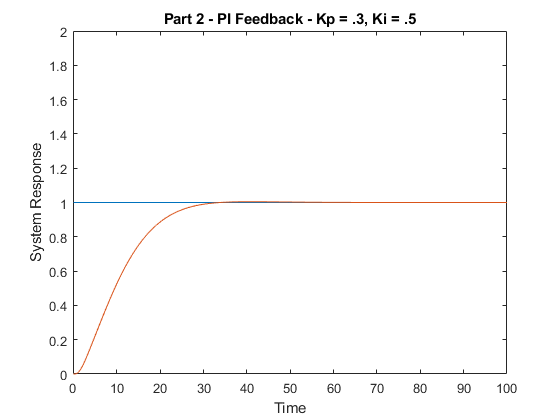

open_system('Lab1_PI.slx');
set_param('Lab1_PI/Kp', 'Gain', num2str(.3));
set_param('Lab1_PI/Ki', 'Gain', num2str(.5));
sim('Lab1_PI.slx');
load("L1_PI_Out.mat");
close_system('Lab1_PI.slx');

plot(L1_PI_Out.signal1);
hold on;
plot(L1_PI_Out.signal2);
hold off;
axis([-0.1 100 0 2]);
xlabel("Time");
ylabel("System Response");
title("Part 2 - PI Feedback - Kp = .3, Ki = .5");

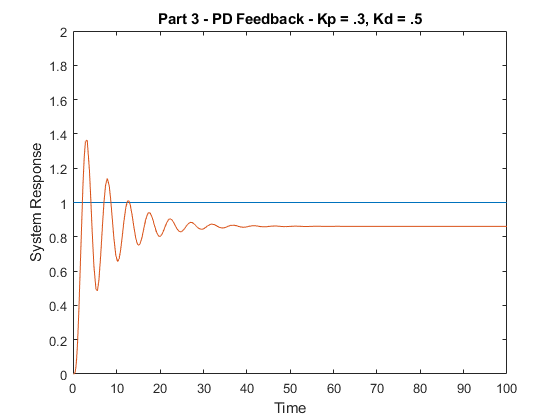

open_system('Lab1_PD.slx');
set_param('Lab1_PD/Kp', 'Gain', num2str(5));
Kd.Value = 1;
sim('Lab1_PD.slx');
load("L1_PD_Out.mat");
save_system('Lab1_PD.slx');
close_system('Lab1_PD.slx');

plot(L1_PD_Out.signal1);
hold on;
plot(L1_PD_Out.signal2);
hold off;
axis([-0.1 100 0 2]);
xlabel("Time");
ylabel("System Response");
title("Part 3 - PD Feedback - Kp = 5, Kd = 1");